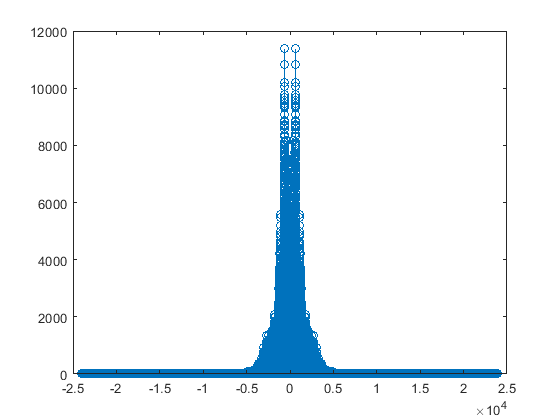

clc

f=5;

% t = 0:0.01:1;
% x = sin(2*pi*f*t);
% %plot(t,x,'m');
% %hold on;
% x = awgn(x,15);
% %plot(t,x,'b');

[x,f]=audioread("Gaata Rahe Mera Dil (Guide).wav");
SR = 44100;
z = x;
x = x(8000:5000000,1);
n = length(x);

%ff=-f/2+0.5-8*f/n:f/n:f/2-0.5+7*f/n;
ff=-f/2:f/n:(f/2);
ff=ff(1:end-1);
Y=abs(fftshift(fft(x)));
stem(ff,Y)


N = 21;
F=10000

F = 10000


f_low = LowPass(N,(F/4)*2*pi/SR)

f_low =    -0.0130   -0.0023    0.0115    0.0275    0.0448    0.0623    0.0787    0.0930    0.1040    0.1110    0.1134    0.1110    0.1040    0.0930    0.0787    0.0623    0.0448    0.0275    0.0115   -0.0023   -0.0130


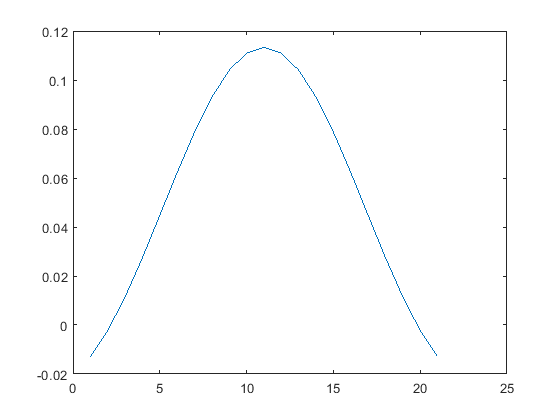

plot(f_low)

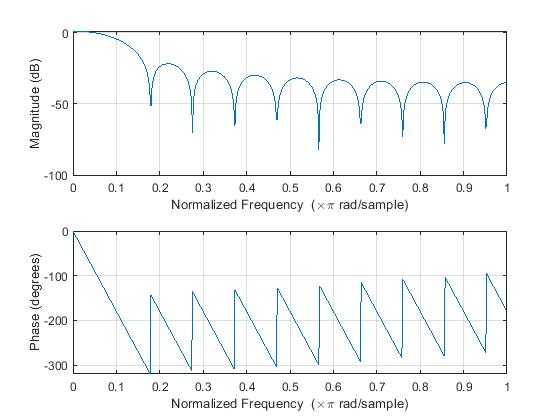

freqz(f_low)

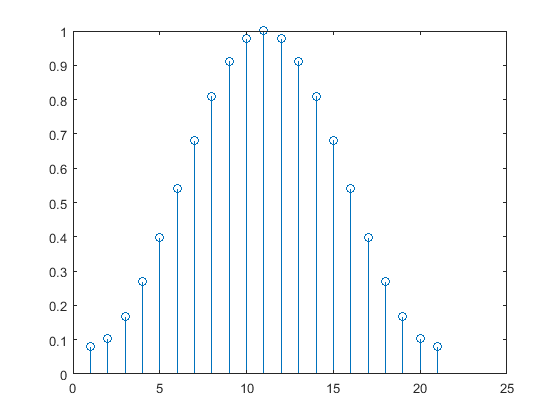

window =     0.0800    0.1025    0.1679    0.2696    0.3979    0.5400    0.6821    0.8104    0.9121    0.9775    1.0000    0.9775    0.9121    0.8104    0.6821    0.5400    0.3979    0.2696    0.1679    0.1025    0.0800


window= hamming_window(N)

hn1=mul(window,f_low)

hn =    -0.0010   -0.0002    0.0019    0.0074    0.0178    0.0336    0.0537    0.0754    0.0949    0.1085    0.1134    0.1085    0.0949    0.0754    0.0537    0.0336    0.0178    0.0074    0.0019   -0.0002   -0.0010


hn1 =    -0.0010   -0.0002    0.0019    0.0074    0.0178    0.0336    0.0537    0.0754    0.0949    0.1085    0.1134    0.1085    0.0949    0.0754    0.0537    0.0336    0.0178    0.0074    0.0019   -0.0002   -0.0010



f_band1 = BandPass(N,(F/4)*2*pi/SR,(F/2)*2*pi/SR)

f_band1 =     0.0367    0.0068   -0.0334   -0.0712   -0.0928   -0.0882   -0.0558   -0.0035    0.0534    0.0971    0.1134    0.0971    0.0534   -0.0035   -0.0558   -0.0882   -0.0928   -0.0712   -0.0334    0.0068    0.0367


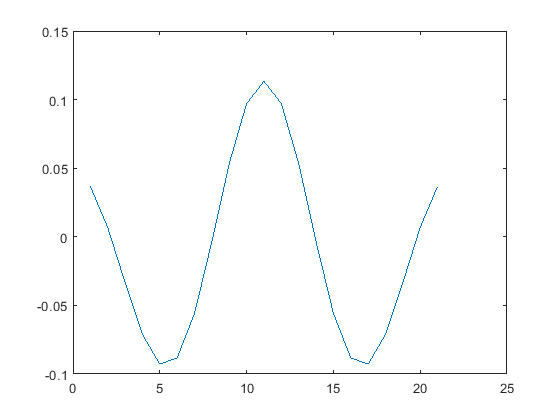

plot(f_band1)

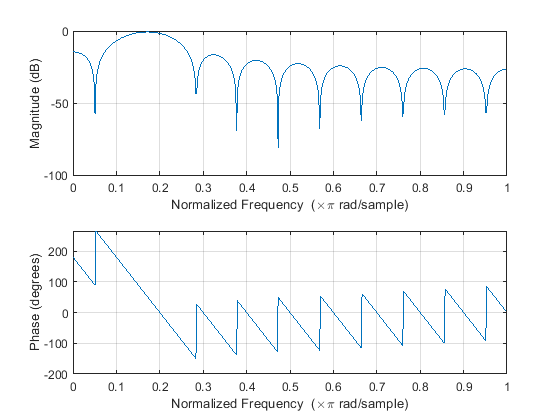

freqz(f_band1)

window =     0.0800    0.1025    0.1679    0.2696    0.3979    0.5400    0.6821    0.8104    0.9121    0.9775    1.0000    0.9775    0.9121    0.8104    0.6821    0.5400    0.3979    0.2696    0.1679    0.1025    0.0800


window= hamming_window(N)

hn2=mul(window,f_band1)

hn =     0.0029    0.0007   -0.0056   -0.0192   -0.0369   -0.0476   -0.0381   -0.0028    0.0487    0.0949    0.1134    0.0949    0.0487   -0.0028   -0.0381   -0.0476   -0.0369   -0.0192   -0.0056    0.0007    0.0029


hn2 =     0.0029    0.0007   -0.0056   -0.0192   -0.0369   -0.0476   -0.0381   -0.0028    0.0487    0.0949    0.1134    0.0949    0.0487   -0.0028   -0.0381   -0.0476   -0.0369   -0.0192   -0.0056    0.0007    0.0029



f_band2 = BandPass(N,(F/2)*2*pi/SR,(3*F/4)*2*pi/SR)

f_band2 =    -0.0540   -0.0113    0.0525    0.0861    0.0548   -0.0254   -0.0950   -0.0963   -0.0232    0.0709    0.1134    0.0709   -0.0232   -0.0963   -0.0950   -0.0254    0.0548    0.0861    0.0525   -0.0113   -0.0540


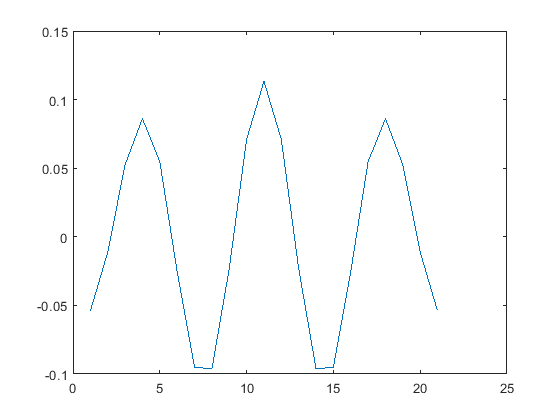

plot(f_band2)

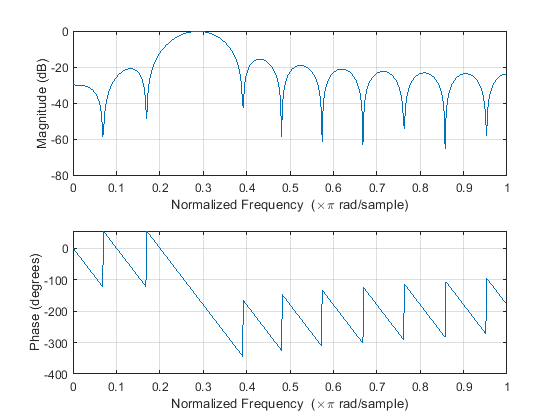

freqz(f_band2)

window =     0.0800    0.1025    0.1679    0.2696    0.3979    0.5400    0.6821    0.8104    0.9121    0.9775    1.0000    0.9775    0.9121    0.8104    0.6821    0.5400    0.3979    0.2696    0.1679    0.1025    0.0800


window= hamming_window(N)

hn3=mul(window,f_band2)

hn =    -0.0043   -0.0012    0.0088    0.0232    0.0218   -0.0137   -0.0648   -0.0781   -0.0211    0.0693    0.1134    0.0693   -0.0211   -0.0781   -0.0648   -0.0137    0.0218    0.0232    0.0088   -0.0012   -0.0043


hn3 =    -0.0043   -0.0012    0.0088    0.0232    0.0218   -0.0137   -0.0648   -0.0781   -0.0211    0.0693    0.1134    0.0693   -0.0211   -0.0781   -0.0648   -0.0137    0.0218    0.0232    0.0088   -0.0012   -0.0043



f_high = HighPass(N,(3*F/4)*2*pi/SR)

f_high =     0.0303    0.0068   -0.0306   -0.0423   -0.0068    0.0514    0.0721    0.0068   -0.1343   -0.2790    0.6599   -0.2790   -0.1343    0.0068    0.0721    0.0514   -0.0068   -0.0423   -0.0306    0.0068    0.0303


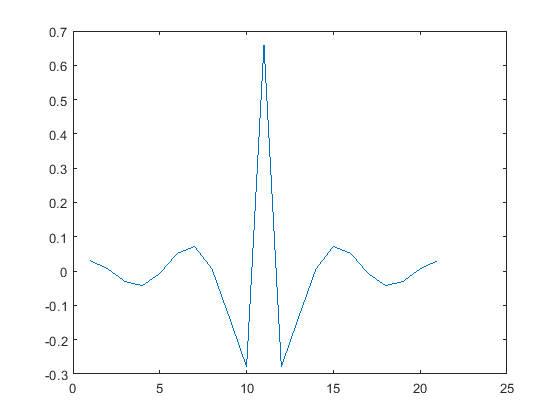

plot(f_high)

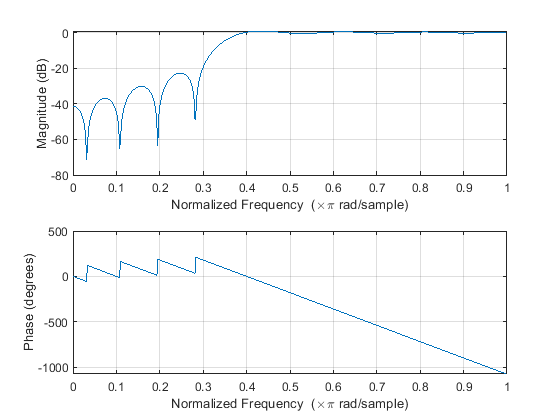

freqz(f_high)

window =     0.0800    0.1025    0.1679    0.2696    0.3979    0.5400    0.6821    0.8104    0.9121    0.9775    1.0000    0.9775    0.9121    0.8104    0.6821    0.5400    0.3979    0.2696    0.1679    0.1025    0.0800


window= hamming_window(N)

hn4=mul(window,f_high)

hn =     0.0024    0.0007   -0.0051   -0.0114   -0.0027    0.0278    0.0492    0.0055   -0.1225   -0.2727    0.6599   -0.2727   -0.1225    0.0055    0.0492    0.0278   -0.0027   -0.0114   -0.0051    0.0007    0.0024


hn4 =     0.0024    0.0007   -0.0051   -0.0114   -0.0027    0.0278    0.0492    0.0055   -0.1225   -0.2727    0.6599   -0.2727   -0.1225    0.0055    0.0492    0.0278   -0.0027   -0.0114   -0.0051    0.0007    0.0024


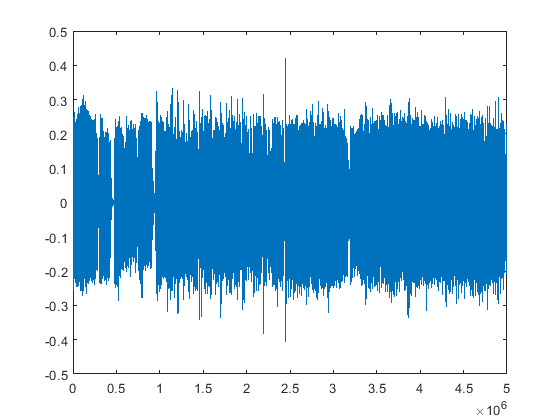


y1=conv(x,hn1);
y2=conv(x,hn2);
y3=conv(x,hn3);
y4=conv(x,hn4);

plot(y1)

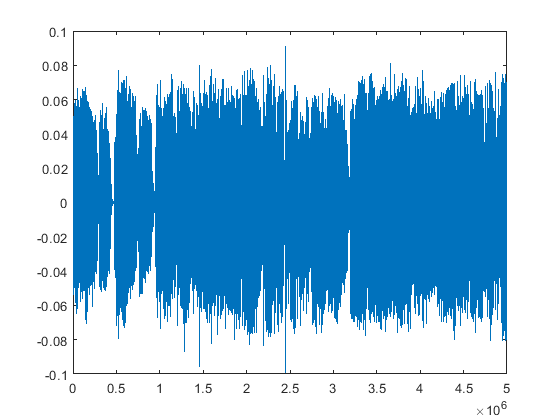

plot(y2)

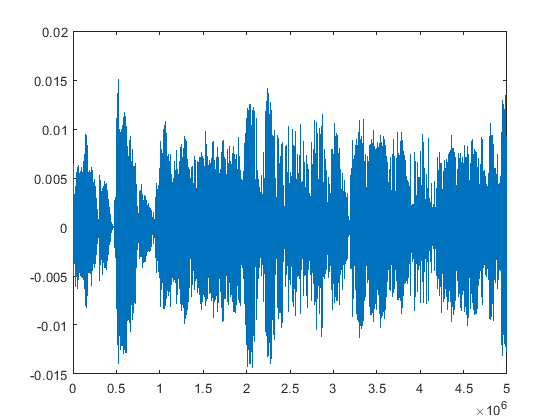

plot(y3)

plot(y4)

de1=zeros(44100,1);

y11 = [y1;de1]

y11 =     0.0000
    0.0001
   -0.0000
   -0.0004
   -0.0013
   -0.0029
   -0.0056
   -0.0095
   -0.0145
   -0.0202


y22 = [y2;de1]

y22 =    -0.0001
   -0.0002
    0.0001
    0.0010
    0.0028
    0.0053
    0.0074
    0.0079
    0.0058
    0.0011


y33 = [y3;de1]

y33 =     0.0002
    0.0003
   -0.0001
   -0.0012
   -0.0024
   -0.0019
    0.0011
    0.0050
    0.0064
    0.0037


y44 = [y4;de1]

y44 =    -0.0001
   -0.0002
    0.0001
    0.0006
    0.0008
   -0.0005
   -0.0028
   -0.0033
    0.0023
    0.0154


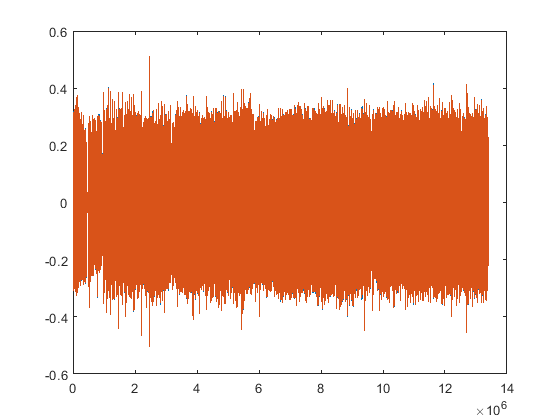

yy = y11+y22+y33+y44;
plot(z)

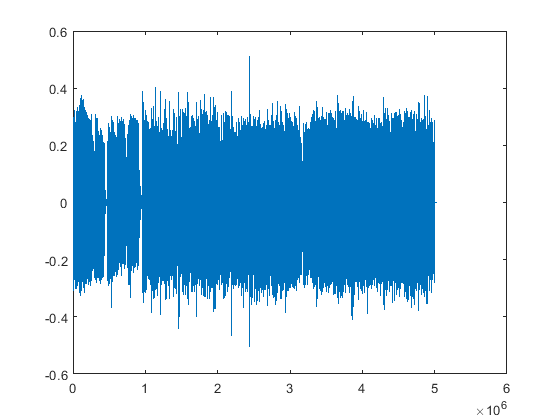

plot(yy)

sound(yy,f)


filename='output_convo.wav'

filename = 'output_convo.wav'

audiowrite(filename,yy,SR);


function hd= LowPass(N,Wc)
    alpha =(N-1)/2;
    n=0:N-1;
    hd=sin(Wc*(n-alpha))./(pi*(n-alpha));
    hd(alpha+1)=Wc/pi;
end

function hd= HighPass(N,Wc)
    alpha =(N-1)/2;
    n=0:N-1;
    hd=(sin(pi*(n-alpha))-sin(Wc*(n-alpha)))./(pi*(n-alpha));
    hd(alpha+1)=1-(Wc/pi);
end

function hd= BandPass(N,Wc_low,Wc_high)
    alpha =(N-1)/2;
    n=0:N-1;
    hd=(sin(Wc_high*(n-alpha))-sin(Wc_low*(n-alpha)))./(pi*(n-alpha));
    hd(alpha+1)=(Wc_high-Wc_low)/pi;
end

function hd= BandStop(N,Wc_low,Wc_high)
    alpha =(N-1)/2;
    n=0:N-1;
    hd=(sin(Wc_low*(n-alpha))-sin(Wc_high*(n-alpha)))./(pi*(n-alpha))+sin(pi*(n-alpha));
    hd(alpha+1)=1-((Wc_low-Wc_high)/pi);
end

function w = hamming_window(N)
n=0:N-1;
w=0.54-0.46*cos(2*pi*n/(N-1));
stem(w)
end

function hn = mul(w,hd)
hn = w.*hd
end

